# Archivos, variables y funciones básicas en Matlab

## Entorno de Matlab

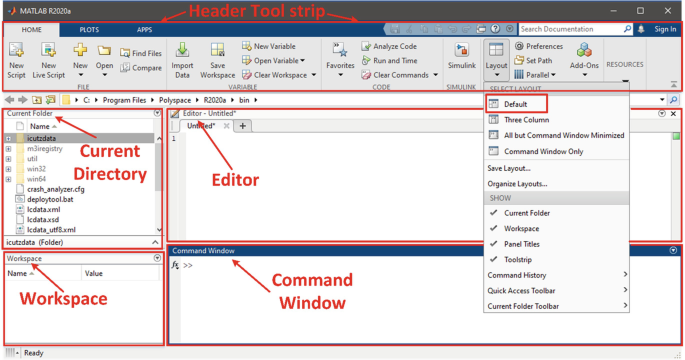

Figura tomada de [[1]](https://link.springer.com/chapter/10.1007/978-3-030-89762-8_1)

## Tipos de archivos

Existen diferentes archivos que se generan en Matlab:

- Archivos que guardan variables del workspace de Matlab** (.mat)  **

- Archivos planos con comandos validos de Matlab** (.m)**

- Archivos tipo notebook que contienen commandos validos de Matlab **(.mlx)** que, a diferencia de los archivos planos, pueden guardar imagenes, comentarios, tablas, variables, etc.

- Archivos editables que guardan figuras **(.fig)**

- Archivos que guardan modelos de simulink **(.slx)**

Matlab es un **lenguage** de programación **interpretado**, es decir, cada comando es evaluado al darle "Enter" o corriendo secciones de archivos.

**Notas:**

- Matlab es sencible a mayúsculas y minúsculas, por ejemplo, Var1 es diferente a var1 en definición de nombres de variables.

- Los archivos nodeben ser nombrados utilizando caracteres especiales (á, é, í, ó, ú, ñ, etc). Por ejemplo, en vez de nombrar un Archivo como *CatañoLópezTaller1* nombrarlo como *CatanoLopezTaller1.*

- Los comentarios en código son definidos por el símbolo de porcentaje (%).

## Tipos de clases de datos básicos

**Numéricos: **incluyen enteros y punto flotante con signo

2,-2, 2.5, -2.5

ans = 2

ans = -2

ans = 2.5000

ans = -2.5000

**Caracteres: **almacenan texto en Matlab, es una secuencia de caracteres

c = 'Hello World'

c = 'Hello World'

**Strings: **es un contenedor de fragmentos de texto, proporciona un conjunto de funciones para trabajar textos como datos.

c = "Hello World"

c = "Hello World"

## Operaciones básicas

**Sintaxis:**

Uso del punto y coma (;) al final de cada linea de código para evitar que se muestre resultado

V = [1,2,3,4];

**Acceder a elementos de vectores:** las posiciones en Matlab empiezan desde 1, por ejemplo:

V(1), V(3)

ans = 1

ans = 3

**Acceder de elementos en matrices: **los índices se definen por filas primero y luego columnas, por ejemplo: 

La segunda fila con tercera columna de la matriz M es 5

M = [1,2,3,4; 
     5,6,7,8];
M(2,3)

ans = 7

Si se quiere obtener todos los elementos de la primera fila se utilizan los dos puntos (:)

M(1,:)

ans =      1     2     3     4


De manera similar se accede a los elementos de la primera columna

M(:,1)

ans =      1
     5


**Operadores aritméticos:**

**Suma de escalares, vectores y matrices:**

b+a

ans = 4

M+M

ans =      2     4     6     8
    10    12    14    16


V+V

ans =      2     4     6     8


**Multiplicación de escalares, vectores y matrices:**

b*a

ans = 3

Para el caso de matrices y vectores, se utiliza la comilla simple (') para trasponerlos 

V*V'

ans = 30

M*M'

ans =     30    70
    70   174


Si se quiere realizar la multiplicación de elemento por elemento de matrices y vectores, se usa la sintaxis de punto y asterisco (.*)

V.*V %[1*1, 2*2, 3*3, 4*4]

ans =      1     4     9    16


M.*M %[1*1, 2*2, 3*3, 4*4; 5*5, 6*6, 7*7, 8*8]

ans =      1     4     9    16
    25    36    49    64


De manera similar, para operar elemento por elemento de matrices y vectores, se usa la sintaxis de punto y operador aritmético:

V./V %[1/1, 2/2, 3/3, 4/4]

ans =      1     1     1     1


V.^V %[1^1, 2^2, 3^3, 4^4]

ans =      1     4    27   256


Para mayor información ver la siguiente tabla (Tomado de [[2]](https://www.mathworks.com/help/matlab/matlab_prog/array-vs-matrix-operations.html))

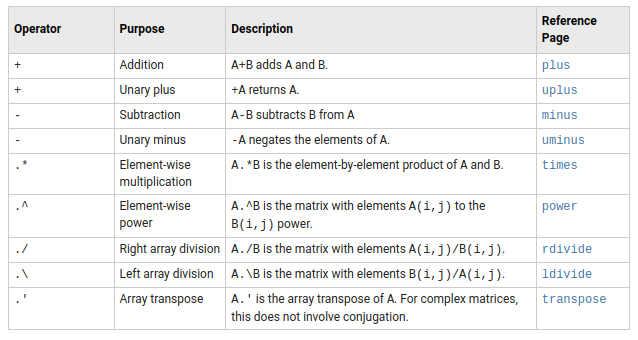

**Funciones elementales:**

Las funciones en Matlab se definen a través de su nombre y en paréntesis se ingresan las entradas necesarias. Por ejemplo:

*Function(input1, input2,..., inputn)*

x = 3;
sin(x)

ans = 0.1411

cos(x)

ans = -0.9900

tan(x)

ans = -0.1425

log(x)

ans = 1.0986

log10(x)

ans = 0.4771

sqrt(x)

ans = 1.7321

Función para crear matrices y vectores de ceros

zeros(3,1) %vector fila de zeros

ans =      0
     0
     0


zeros(1,2) %vector columna de zeros

ans =      0     0


zeros(3,4) %matriz de tres filas y cuatro columnas

ans =      0     0     0     0
     0     0     0     0
     0     0     0     0


**Funciones complementarias:**

Limpiar el worksapce

clear

Limpiar command window

clc

Agregar carpetas a la ruta de acceso de MAtlab

addpath IntroMatlab/

Buscar documentación de una función de Matlab

help addpath

 addpath Add folder to search path.
    addpath FOLDERNAME prepends the specified folder to the current
    matlabpath.  Surround FOLDERNAME in quotes if the name contains a
    space.  If FOLDERNAME is a set of multiple folders separated by path
    separators, then each of the specified folders will be added.
 
    addpath FOLDERNAME1 FOLDERNAME2 FOLDERNAME3 ...  prepends all the 
    specified folders to the path.
 
    addpath ... -END    appends the specified folders.
    addpath ... -BEGIN  prepends the specified folders.
    addpath ... -FROZEN disables folder change detection for folders
                        being added.
 
    Use the functional form of addpath, such as 
    addpath('folder1','folder2',...), when the folder specification is 
    a variable or string.
 
    P = addpath(...) returns the path prior to adding th

## Ejemplo de gráficos en Matlab (básico)

Se quiere graficar la función $f(t)=1+0.5\exp(-0.2 t)\sin(0.8t)$para $t=[1,60]$

1. Se define la variable independiente $t$ 

t = 1:1:60; %vetor fila con elementos de 1 a 60

2. Se evalua la función $f(t)$ y se guarda en una variable $y$

y = 1+0.5*exp(-0.2*t).*sin(0.8*t);

3. Se grafica el resultado de $y$

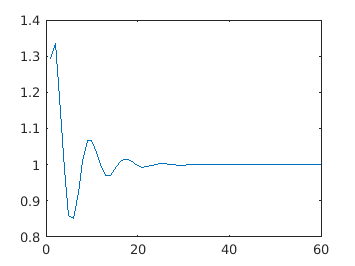

plot(t,y) %Primero la variable independiente (x) y luego la dependiente (y)